% This script loads and stores multiple NJ data files, runs the respective models

clear; clc;

data1 = shuze_parse_rawdata_exp3("pilot1", inf, true);

n_nonresponsive_trials =      0     0
     0     0
     0     0
     0     0
     0     0


data2 = shuze_parse_rawdata_exp3("exp1", inf, true);

n_nonresponsive_trials =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


data3 = shuze_parse_rawdata_exp3("exp2", inf, true);

n_nonresponsive_trials =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


data = data1;
data.NJ = [data.NJ data2.NJ data3.NJ];

## append qualtrics data

dt = analyze_qualtrics_csv();
for s = 1:length(data.NJ)
    subj = data.NJ(s).ID;
    data.NJ(s).survey = dt.(subj);
end

## get data variables

allBDI = arrayfun(@(d) sum(d.survey.BDI), data.NJ);
minBDI = min(allBDI);
maxBDI = max(allBDI);
scaledBDI = (allBDI - minBDI) ./ (maxBDI - minBDI);

MSE_all = [];
MSE_low = [];
MSE_high = [];
subj = {};
SHAPS = [];
TEPS = [];
TEPS_a = [];
TEPS_c = [];
BDI = [];
BDI_anhedonia = [];
BDI_concentration = [];

for s = 1:length(data.NJ)
    my_dat = data.NJ(s);
    est_stim = my_dat.est_stim;
    est_stim(est_stim > 100) = NaN;

    subj = [subj; my_dat.ID];
    MSE_all = [MSE_all; nanmean((est_stim - my_dat.true_stim).^2)];
    m_low = my_dat.cond == 0.4;
    m_high = my_dat.cond == 2;
    MSE_low = [MSE_low; nanmean((est_stim(m_low) - my_dat.true_stim(m_low)).^2)];
    MSE_high = [MSE_high; nanmean((est_stim(m_high) - my_dat.true_stim(m_high)).^2)];
    
    SHAPS = [SHAPS; sum(my_dat.survey.SHAPS)];
    TEPS = [TEPS; sum(my_dat.survey.TEPS)];
    TEPS_a = [TEPS_a; sum(my_dat.survey.TEPS_anticipatory)];
    TEPS_c = [TEPS_c; sum(my_dat.survey.TEPS_consummatory)];
    
    BDI(s,1)           = scaledBDI(s);
    BDI_anhedonia = [BDI_anhedonia; my_dat.survey.BDI(4)];
    BDI_concentration = [BDI_concentration; my_dat.survey.BDI(19)];

end

MSE_diff = MSE_low - MSE_high;
MSE_diff(MSE_diff > 100) = NaN;
BDI_low = BDI < nanmedian(BDI);
BDI_high = BDI >= nanmedian(BDI);

tbl = table(MSE_all, MSE_diff, MSE_high, MSE_low, ...
            normalize(SHAPS), normalize(TEPS), normalize(TEPS_a), normalize(TEPS_c), normalize(BDI), ...
            normalize(BDI_anhedonia), normalize(BDI_concentration), subj, ...
            'VariableNames', ...
           {'MSE_all','MSE_diff','MSE_high','MSE_low', ...
            'SHAPS','TEPS','TEPS_a','TEPS_c','BDI', ...
            'BDI_anhedonia','BDI_concentration','subj'});

fitlm(tbl, 'MSE_diff ~ BDI')

ans = Linear regression model:
    MSE_diff ~ 1 + BDI

Estimated Coefficients:
                   Estimate      SE      tStat      pValue 
                   ________    ______    ______    ________

    (Intercept)     4.3421     2.4792    1.7514    0.082975
    BDI              4.661     2.5624     1.819     0.07193


Number of observations: 101, Error degrees of freedom: 99
Root Mean Squared Error: 24.9
R-squared: 0.0323,  Adjusted R-Squared: 0.0226
F-statistic vs. constant model: 3.31, p-value = 0.0719

## Plot BDI

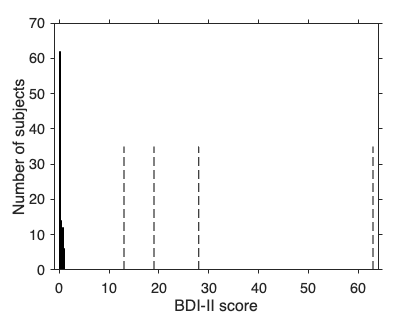

close all
histogram(BDI); hold on
set(gca,'fontsize',18,'tickdir','out')
plot([13 13],[0 35],'k--')
plot([19 19],[0 35],'k--')
plot([28 28],[0 35],'k--')
plot([63 63],[0 35],'k--')
xlim([-1 64])
xlabel('BDI-II score')
ylabel('Number of subjects')


%%
mdl_BDI_concentration = fitlm(tbl, 'BDI_concentration ~ BDI_anhedonia');
mdl_BDI_anhedonia = fitlm(tbl, 'BDI_anhedonia ~ BDI_concentration');

BDI_concentration_resid = mdl_BDI_concentration.Residuals.Raw;
BDI_anhedonia_resid = mdl_BDI_anhedonia.Residuals.Raw;

%%

tbl_tall = table([MSE_low; MSE_high], [false(size(MSE_low)); true(size(MSE_high))], ...
            normalize([BDI; BDI]), ...
            normalize([BDI_anhedonia; BDI_anhedonia]), ...
            normalize([BDI_concentration; BDI_concentration]), [subj; subj], ...
            'VariableNames', ...
           {'MSE','high_incentive','BDI','BDI_anhedonia','BDI_concentration','subj'});

clc




%%
clc
mdl_anhed_conc = fitlme(tbl_tall, ['MSE ~ high_incentive*BDI_anhedonia*BDI_concentration - ' ...
                                         'BDI_anhedonia:BDI_concentration - ' ...
                                         'high_incentive:BDI_anhedonia:BDI_concentration + ' ...
                                         '(BDI_anhedonia - 1|subj) + (BDI_concentration - 1|subj) + (1|subj)'])

mdl_anhed_conc = Linear mixed-effects model fit by ML

Model information:
    Number of observations             206
    Fixed effects coefficients           6
    Random effects coefficients        309
    Covariance parameters                4

Formula:
    MSE ~ 1 + high_incentive*BDI_anhedonia + high_incentive*BDI_concentration + (BDI_anhedonia | subj) + (BDI_concentration | subj) + (1 | subj)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    2129.7    2163    -1054.9          2109.7  

Fixed effects coefficients (95% CIs):
    Name                                          Estimate    SE        tStat      DF     pValue        Lower      Upper   
    {'(Intercept)'                       }         92.165     5.8404     15.781    200    5.6532e-37     80.649      103.68
    {'high_incentive_1'                  }        -6.6278     2.8658    -2.3127    200      0.021754    -12.

## plot that bad boy

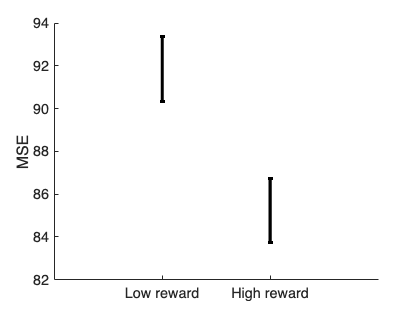

figure; hold on
wse_all = wse([MSE_low MSE_high]);
errorbar(1, nanmean(MSE_low), wse_all(1), 'k', 'linewidth', 4);
errorbar(2, nanmean(MSE_high), wse_all(1), 'k', 'linewidth', 4);
xlim([0 3])
set(gca,'xtick',1:2,'xticklabel',{'Low reward','High reward'})
set(gca,'fontsize',18)
ylabel('MSE')


clc
mdl_all = fitlme(tbl_tall, 'MSE ~ high_incentive + (1|subj)')

mdl_all = Linear mixed-effects model fit by ML

Model information:
    Number of observations             206
    Fixed effects coefficients           2
    Random effects coefficients        103
    Covariance parameters                2

Formula:
    MSE ~ 1 + high_incentive + (1 | subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2149.3    2162.6    -1070.6          2141.3  

Fixed effects coefficients (95% CIs):
    Name                        Estimate    SE        tStat      DF     pValue        Lower     Upper   
    {'(Intercept)'     }         91.856      6.336     14.497    204    3.3214e-33    79.364      104.35
    {'high_incentive_1'}        -6.6278     3.0187    -2.1956    204      0.029251    -12.58    -0.67588

Random effects covariance parameters (95% CIs):
Group: subj (103 Levels)
    Name1                  Name2                  Type  

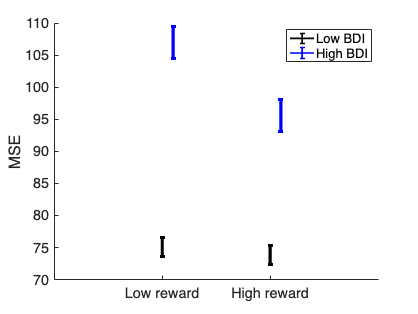

%%


figure; hold on
perf_low_BDI_low = MSE_low(BDI_low);
perf_low_BDI_high = MSE_low(BDI_high);
wse_BDI_low = wse([MSE_low(BDI_low) MSE_high(BDI_low)]);
wse_BDI_high = wse([MSE_low(BDI_high) MSE_high(BDI_high)]);

perf_high_BDI_low = MSE_high(BDI_low);
perf_high_BDI_high = MSE_high(BDI_high);
t(1) = errorbar(1, nanmean(perf_low_BDI_low), wse_BDI_low(1),'k','linewidth',4);
t(2) = errorbar(1.1, nanmean(perf_low_BDI_high), wse_BDI_high(1),'b','linewidth',4);

errorbar(2, nanmean(perf_high_BDI_low), wse_BDI_low(2),'k','linewidth',4)
errorbar(2.1, nanmean(perf_high_BDI_high), wse_BDI_high(2),'b','linewidth',4)
xlim([0 3])
set(gca,'xtick',1:2,'xticklabel',{'Low reward','High reward'}, 'fontsize', 18)
ylabel('MSE')
legend(t,{'Low BDI','High BDI'})

hold off;

subj = {};
bonus = [];
for s = 1:length(data3.NJ)
    subj = [subj; data3.NJ(s).ID];
    bonus = [bonus; data3.NJ(s).bonus];
end
tbl = table(subj, bonus);

## **Brock Data Cleaning + Outlier Detection**

% Unique numeric IDs (Subject values)
IDs = {data.NJ.ID};

% mapping 
[uniqueIDs, ~, idx] = unique(IDs, 'stable'); 

% Assign a new field "subject" with sequential integers
for i = 1:length(data.NJ)
    data.NJ(i).subject = idx(i);
end

% Define the mapping of old field names to new field names
rename_fields = {'avg_true_stim', 'avg_stim'; 
                 'true_stim', 'stimulus';
                 'cond', 'incentive';
                 'est_stim', 'estimate'};

% Loop through each field renaming pair
for i = 1:size(rename_fields, 1)
    oldField = rename_fields{i, 1};
    newField = rename_fields{i, 2};
    
    % Iterate over all elements in data.NJ (array of structures)
    for j = 1:numel(data.NJ)
        if isfield(data.NJ, oldField)
            data.NJ(j).(newField) = data.NJ(j).(oldField); % Copy old field to new field
        end
    end
    
    % Remove the old field (only once since rmfield operates on the whole struct array)
    if isfield(data.NJ, oldField)
        data.NJ = rmfield(data.NJ, oldField);
    end
end


% 120x1 double (1-40 repeated 3 times)
trial_sequence = repmat((1:40)', 3, 1);

for i = 1:length(data.NJ)
    data.NJ(i).trial = trial_sequence; 
end

## Calculating MSE Values (Real Data --> Outlier Detection)

threshold_trials = 0.05;   % max allowed fraction of bad/outlier trials per subject
outlier_cutoff   = 100;    % est >= 100 --> outlier

allNJ = data.NJ;
numSubj = numel(allNJ);

cleanNJ = struct([]);      % hold only the kept+trimmed subjects
cnt     = 0;

for i = 1:numSubj
    subj = allNJ(i);
    
    % identify bad trials
    outlier_bad = subj.estimate >= outlier_cutoff;
    nan_bad = isnan(subj.estimate);
    bad = outlier_bad | nan_bad;

    prop_bad = mean(bad);
    
    % skip subjects with too many outliers
    if prop_bad >= threshold_trials
        continue
    end

    cnt = cnt + 1;
    
    %  scalar fields (same) 
    cleanNJ(cnt).ID                    = subj.ID;
    cleanNJ(cnt).subject               = subj.subject;
    cleanNJ(cnt).cutoff                = subj.cutoff;
    cleanNJ(cnt).nonresponsive_trials  = subj.nonresponsive_trials;
    cleanNJ(cnt).final_bonus           = subj.final_bonus;
    cleanNJ(cnt).task                  = subj.task;
    cleanNJ(cnt).bonus                 = subj.bonus;
    cleanNJ(cnt).survey                = subj.survey;

    % keep stimulus the same
    cleanNJ(cnt).stimulus = subj.stimulus;

    % replace outlier trials/guesses with mean of valid estimates
    cleanNJ(cnt).estimate = subj.estimate;

    % valid estimates by condition
    low_cond = double(subj.incentive) == 1;
    high_cond = double(subj.incentive) ~= 1;
    
    valid_low_est = subj.estimate(low_cond & ~bad);
    valid_high_est = subj.estimate(high_cond & ~bad);
    
    mean_low_est = mean(valid_low_est, 'omitnan');
    mean_high_est = mean(valid_high_est, 'omitnan');

    % replace outliers with condition-specific means
    cleanNJ(cnt).estimate(low_cond & bad) = mean_low_est;
    cleanNJ(cnt).estimate(high_cond & bad) = mean_high_est;

    % everything else stays the same
    cleanNJ(cnt).incentive = subj.incentive;
    cleanNJ(cnt).avg_stim = subj.avg_stim;
    cleanNJ(cnt).block = subj.block;
    cleanNJ(cnt).acc = subj.acc;
    cleanNJ(cnt).r = subj.r;
end

cleanBDI = arrayfun(@(d) sum(d.survey.BDI), cleanNJ(:));
minBDI = min(cleanBDI);
maxBDI = max(cleanBDI);
scaledBDI = (cleanBDI - minBDI) ./ (maxBDI - minBDI);

BDI_low = cleanBDI < nanmedian(cleanBDI);
BDI_high = cleanBDI >= nanmedian(cleanBDI);

% original (Sam's) RI model
results_RI = fit_models_brock_RI(cleanNJ);

Subject 1
Initial parameter values (x0):
    0.0002   24.6644   17.9538

Initial parameter values (x0):
    0.0139    3.3472    1.9966

Initial parameter values (x0):
    0.0030    4.2494   29.4282

Initial parameter values (x0):
    0.0128    6.8602    3.2373

Initial parameter values (x0):
    0.0008   30.7211   38.9469

Subject 2
Initial parameter values (x0):
    0.0067    4.5265   17.2419

Initial parameter values (x0):
    0.0038    5.4000    5.5510

Initial parameter values (x0):
    0.0113    6.5886    3.8528

Initial parameter values (x0):
    0.0027   37.7012   39.8066

Initial parameter values (x0):
    0.0018    6.0218   23.4195

Subject 3
Initial parameter values (x0):
    0.0058    8.2496   16.1475

Initial parameter values (x0):
    0.0091   10.9681   28.3190

Initial parameter values (x0):
    0.0022   34.5487   12.2552

Initial parameter values (x0):
    0.0139   36.6504   41.2297

Initial parameter values (x0):
    0.0045    2.9335    2.0536

Subject 4
Initial paramet


% BDI "turned off" (BDI_intact = 0)
results_BDI_off = fit_models_brock_BDI_intact(cleanNJ, 0);

Subject 1
Initial parameter values (x0):
    0.0820   47.0116  -13.7794   25.3627

Initial parameter values (x0):
    0.0236    2.6958  -15.3398   24.4266

Initial parameter values (x0):
    0.0480   42.5310   -1.3329   37.3410

Initial parameter values (x0):
    0.0702    5.3484    0.4062   21.0691

Initial parameter values (x0):
    0.0641   38.9944   -8.5690   10.8548

Subject 2
Initial parameter values (x0):
    0.0345   12.2530    4.7109   46.8297

Initial parameter values (x0):
    0.0893   26.3551  -18.2508   14.5611

Initial parameter values (x0):
    0.0298   43.0217    3.2335   34.7260

Initial parameter values (x0):
    0.0206   16.9279  -19.1355    2.8852

Initial parameter values (x0):
    0.0657    0.6047  -12.9025   39.8460

Subject 3
Initial parameter values (x0):
    0.0417   43.0571   -0.5226   37.7255

Initial parameter values (x0):
    0.0834   15.1648   -8.0684   13.1341

Initial parameter values (x0):
    0.0713    3.2600  -11.3651    2.7565

Initial parameter val


% full BDI model (BDI_intact = 1)
results_BDI_full = fit_models_brock_BDI_intact(cleanNJ, 1);

Subject 1
Initial parameter values (x0):
    0.0685   39.9127  -20.6140   36.2872

Initial parameter values (x0):
    0.0882   42.1694  -22.6419   48.5606

Initial parameter values (x0):
    0.0603    7.7961  -19.2440   24.8292

Initial parameter values (x0):
    0.0130   21.3919  -13.3575    3.1808

Initial parameter values (x0):
    0.0880    2.9917   -9.2608   46.3178

Subject 2
Initial parameter values (x0):
    0.0087   49.5412  -18.8245   38.9586

Initial parameter values (x0):
    0.0318   36.8805  -12.7122    2.0761

Initial parameter values (x0):
    0.0009   36.2262    3.4683   19.8467

Initial parameter values (x0):
    0.0753   37.5962   -1.2112   37.6712

Initial parameter values (x0):
    0.0471    2.1341   -5.7469    5.7884

Subject 3
Initial parameter values (x0):
    0.0642   29.2456  -15.8051   35.8507

Initial parameter values (x0):
    0.0880    6.9155  -22.4475   39.5826

Initial parameter values (x0):
    0.0024   35.6769    4.4602    5.8427

Initial parameter val

## Simulations (RI Model)

data_synth_RI = cleanNJ;

if isfield(results_RI, 'latents') && isstruct(results_RI.latents)
    latents_RI = results_RI.latents;  % keep only non-outlier subjects
    num_subjects_RI = numel(latents_RI);
    
    for i = 1:num_subjects_RI
        pred_estimate = latents_RI(i).log_estimate;
        pred_logvar = latents_RI(i).log_var;

        log_estimate_samp = pred_estimate + sqrt(pred_logvar) .* randn(size(pred_estimate));
        synthetic_estimate = round(exp(log_estimate_samp));
        synthetic_estimate(synthetic_estimate < 1) = 1;
        
        data_synth_RI(i).estimate = synthetic_estimate;
    end
else
    error('results_RI.latents is missing or not in expected format.');
end



## Simulation (BDI Off)

data_synth_BDI_off = cleanNJ;

if isfield(results_BDI_off, 'latents') && isstruct(results_BDI_off.latents)
    latents_BDI_off = results_BDI_off.latents;  % keep only non-outlier subjects
    num_subjects_BDI_off = numel(latents_BDI_off);
    
    for i = 1:num_subjects_BDI_off
        pred_estimate = latents_BDI_off(i).log_estimate;
        pred_logvar = latents_BDI_off(i).log_var;

        log_estimate_samp = pred_estimate + sqrt(pred_logvar) .* randn(size(pred_estimate));
        synthetic_estimate = round(exp(log_estimate_samp));
        synthetic_estimate(synthetic_estimate < 1) = 1;
        
        data_synth_BDI_off(i).estimate = synthetic_estimate;
    end
else
    error('results_BDI_off.latents is missing or not in expected format.');
end

## Simulation (BDI Full)

data_synth_BDI_full = cleanNJ;

if isfield(results_BDI_full, 'latents') && isstruct(results_BDI_full.latents)
    latents_BDI_full = results_BDI_full.latents;  % keep only non-outlier subjects
    num_subjects_BDI_full = numel(latents_BDI_full);
    
    for i = 1:num_subjects_BDI_full
        pred_estimate = latents_BDI_full(i).log_estimate;
        pred_logvar = latents_BDI_full(i).log_var;
        
        log_estimate_samp = pred_estimate + sqrt(pred_logvar) .* randn(size(pred_estimate));
        synthetic_estimate = round(exp(pred_estimate + pred_logvar/2));
        synthetic_estimate(synthetic_estimate < 1) = 1;
        
        data_synth_BDI_full(i).estimate = synthetic_estimate;
    end
else
    error('results_BDI_full.latents is missing or not in expected format.');
end

results_synth_RI = fit_models_brock_RI(data_synth_RI);

Subject 1
Initial parameter values (x0):
    0.0059   31.7852   11.4320

Initial parameter values (x0):
    0.0142   40.6852   31.5450

Initial parameter values (x0):
    0.0090   20.8913   41.5012

Initial parameter values (x0):
    0.0065   40.3678   23.7456

Initial parameter values (x0):
    0.0087   22.8650   30.2054

Subject 2
Initial parameter values (x0):
    0.0135   23.0665    9.2632

Initial parameter values (x0):
    0.0047   23.9816   19.9106

Initial parameter values (x0):
    0.0141   40.5470   29.8409

Initial parameter values (x0):
    0.0072   17.1175   15.6272

Initial parameter values (x0):
    0.0084   26.8045   32.3903

Subject 3
Initial parameter values (x0):
    0.0043   32.7224   30.7374

Initial parameter values (x0):
    0.0005   20.6611   38.7653

Initial parameter values (x0):
    0.0006   40.7116    7.3676

Initial parameter values (x0):
    0.0005   24.7849   32.9519

Initial parameter values (x0):
    0.0084   21.8141   30.0624

Subject 4
Initial paramet

results_synth_BDI_off = fit_models_brock_BDI_intact(data_synth_BDI_off, 0) 

Subject 1
Initial parameter values (x0):
    0.0362   11.6276  -17.2466    1.9957

Initial parameter values (x0):
    0.0212   43.0878   -4.5158    5.7533

Initial parameter values (x0):
    0.0590   30.2954  -12.0918   10.2713

Initial parameter values (x0):
    0.0596   36.4472  -15.6937   33.1419

Initial parameter values (x0):
    0.0392   46.0080   -6.2044    8.6218

Subject 2
Initial parameter values (x0):
    0.0821   19.7330    4.9765   12.0219

Initial parameter values (x0):
    0.0068   10.2575  -20.0419   38.3248

Initial parameter values (x0):
    0.0899   35.5829   -8.3099   45.9070

Initial parameter values (x0):
    0.0120   31.3133  -11.8970   30.3475

Initial parameter values (x0):
    0.0207   30.0132   -5.0181   47.7115

Subject 3
Initial parameter values (x0):
    0.0255    8.2167  -18.0955    9.1887

Initial parameter values (x0):
    0.0533    3.2713   -2.6019   32.7199

Initial parameter values (x0):
    0.0165    2.2984   -5.9055   29.3992

Initial parameter val

results_synth_BDI_off = struct with fields:
          K: 4
      param: [1×4 struct]
     likfun: @(x,data)likfun_RI_inline(x,data,BDI_intact)
    logpost: [-98.5757 -28.1501 25.0377 70.4321 -77.6962 39.9706 -33.1569 45.4016 9.3571 -30.9539 40.8522 -25.5645 -42.2290 -10.4331 29.9233 28.2243 1.9176 18.2834 69.6708 22.2575 61.0067 119.0395 -29.2606 44.5705 -21.0206 10.5932 … ] (1×98 double)
     loglik: [-98.5757 -28.1501 25.0377 70.4321 -77.6962 39.9706 -33.1569 45.4016 9.3571 -30.9539 40.8522 -25.5645 -42.2290 -10.4331 29.9233 28.2243 1.9176 18.2834 69.6708 22.2575 61.0067 119.0395 -29.2606 44.5705 -21.0206 10.5932 … ] (1×98 double)
          x: [98×4 double]
          H: {1×98 cell}
        bic: [98×1 double]
        aic: [98×1 double]
    latents: [1×98 struct]


results_synth_BDI_full = fit_models_brock_BDI_intact(data_synth_BDI_full, 1) 

Subject 1
Initial parameter values (x0):
    0.0453    9.4111  -21.0344   48.8967

Initial parameter values (x0):
    0.0279    2.4250  -23.8137   41.9875

Initial parameter values (x0):
    0.0018   49.2711  -16.5848   45.7572

Initial parameter values (x0):
    0.0337   32.5199   -4.3255    1.0177

Initial parameter values (x0):
    0.0847   14.0012  -18.8635   13.3497

Subject 2
Initial parameter values (x0):
    0.0748   38.4732   -2.5736   41.6223

Initial parameter values (x0):
    0.0503   42.8450  -10.9789    8.0905

Initial parameter values (x0):
    0.0453   44.7852   -0.4303   28.1153

Initial parameter values (x0):
    0.0352    4.2911   -9.9955    3.8105

Initial parameter values (x0):
    0.0240   28.3847   -5.0713    5.1471

Subject 3
Initial parameter values (x0):
    0.0827   36.0835  -23.3405   21.0502

Initial parameter values (x0):
    0.0499   29.5562  -20.3535   25.3308

Initial parameter values (x0):
    0.0334   14.3502  -13.7287   19.7293

Initial parameter val

results_synth_BDI_full = struct with fields:
          K: 4
      param: [1×4 struct]
     likfun: @(x,data)likfun_RI_inline(x,data,BDI_intact)
    logpost: [-83.3966 174.0696 180.5567 209.2007 124.4205 182.0779 -80.8493 182.8045 -82.6663 183.4808 217.1756 182.3948 39.0739 178.1930 -82.3841 180.8601 219.8075 179.7594 185.9406 224.9464 191.9473 238.5216 186.5394 182.7977 -81.3938 … ] (1×98 double)
     loglik: [-83.3966 174.0696 180.5567 209.2007 124.4205 182.0779 -80.8493 182.8045 -82.6663 183.4808 217.1756 182.3948 39.0739 178.1930 -82.3841 180.8601 219.8075 179.7594 185.9406 224.9464 191.9473 238.5216 186.5394 182.7977 -81.3938 … ] (1×98 double)
          x: [98×4 double]
          H: {1×98 cell}
        bic: [98×1 double]
        aic: [98×1 double]
    latents: [1×98 struct]


% Comparing latents
function summary_stats = compute_latent_summaries(latents_struct)
    num_subjects = numel(latents_struct);
    
    % summary stats structure
    summary_stats = struct('mean_log_estimate', zeros(num_subjects, 1), ...
                          'mean_confidence', zeros(num_subjects, 1), ...
                          'mean_log_var', zeros(num_subjects, 1), ...
                          'median_log_estimate', zeros(num_subjects, 1), ...
                          'median_confidence', zeros(num_subjects, 1), ...
                          'median_log_var', zeros(num_subjects, 1), ...
                          'std_log_estimate', zeros(num_subjects, 1), ...
                          'std_confidence', zeros(num_subjects, 1), ...
                          'std_log_var', zeros(num_subjects, 1), ...
                          'min_log_var', zeros(num_subjects, 1), ...
                          'max_log_var', zeros(num_subjects, 1));
    
    % calc summary statistics
    for i = 1:num_subjects
        % latent variables for this subject
        log_estimate = latents_struct(i).log_estimate;
        confidence = latents_struct(i).confidence;
        log_var = latents_struct(i).log_var;
        
        % means
        summary_stats.mean_log_estimate(i) = mean(log_estimate, 'omitnan');
        summary_stats.mean_confidence(i) = mean(confidence, 'omitnan');
        summary_stats.mean_log_var(i) = mean(log_var, 'omitnan');
        
        % medians
        summary_stats.median_log_estimate(i) = median(log_estimate, 'omitnan');
        summary_stats.median_confidence(i) = median(confidence, 'omitnan');
        summary_stats.median_log_var(i) = median(log_var, 'omitnan');
        
        % standard deviations
        summary_stats.std_log_estimate(i) = std(log_estimate, 'omitnan');
        summary_stats.std_confidence(i) = std(confidence, 'omitnan');
        summary_stats.std_log_var(i) = std(log_var, 'omitnan');
        
        % Min / max of log_var
        summary_stats.min_log_var(i) = min(log_var, [], 'omitnan');
        summary_stats.max_log_var(i) = max(log_var, [], 'omitnan');
    end
end

summary_stats_RI = compute_latent_summaries(results_RI.latents);
summary_stats_synth_RI = compute_latent_summaries(results_synth_RI.latents);

## MSE Simulations vs. Real Data Scatterplots

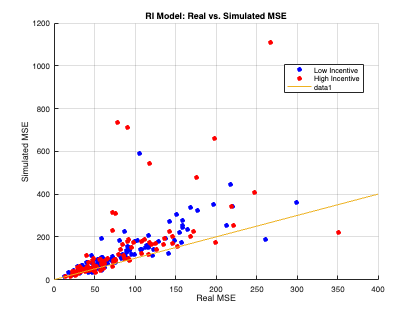

numSubjects = numel(cleanNJ);
MSE_real_low = zeros(numSubjects, 1);   % Low incentive
MSE_real_high = zeros(numSubjects, 1);  % High incentive
MSE_sim_RI_low = zeros(numSubjects, 1);
MSE_sim_RI_high = zeros(numSubjects, 1);
MSE_sim_BDI_off_low = zeros(numSubjects, 1);
MSE_sim_BDI_off_high = zeros(numSubjects, 1);
MSE_sim_BDI_full_low = zeros(numSubjects, 1);
MSE_sim_BDI_full_high = zeros(numSubjects, 1);

% MSEs for each condition
for i = 1:numSubjects
    % Get the true stimulus for subject i
    real_stim = cleanNJ(i).stimulus;
    
    % Get the estimates and handle outliers
    real_est = cleanNJ(i).estimate;
    real_est(real_est > 100) = NaN; % excluding responses above 100
    
    % incentive condition (convert to binary indicator)
    raw_cond = cleanNJ(i).incentive;
    cond_low = (raw_cond == 0.4);  % Low incentive (0.4)
    cond_high = (raw_cond == 2);   % High incentive (2)
    
    % real MSE for each condition
    MSE_real_low(i) = mean((real_est(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_real_high(i) = mean((real_est(cond_high) - real_stim(cond_high)).^2, 'omitnan');
    
    % simulated MSE for each model and condition
    MSE_sim_RI_low(i) = mean((data_synth_RI(i).estimate(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_sim_RI_high(i) = mean((data_synth_RI(i).estimate(cond_high) - real_stim(cond_high)).^2, 'omitnan');
    
    MSE_sim_BDI_off_low(i) = mean((data_synth_BDI_off(i).estimate(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_sim_BDI_off_high(i) = mean((data_synth_BDI_off(i).estimate(cond_high) - real_stim(cond_high)).^2, 'omitnan');
    
    MSE_sim_BDI_full_low(i) = mean((data_synth_BDI_full(i).estimate(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_sim_BDI_full_high(i) = mean((data_synth_BDI_full(i).estimate(cond_high) - real_stim(cond_high)).^2, 'omitnan');
end

% Original RI Model
figure;
hold on;
scatter(MSE_real_low, MSE_sim_RI_low, 'b', 'filled', 'o');  % Blue for low incentive
scatter(MSE_real_high, MSE_sim_RI_high, 'r', 'filled', 'o'); % Red for high incentive
hold off;
xlabel('Real MSE');
ylabel('Simulated MSE');
title('RI Model: Real vs. Simulated MSE');
legend('Low Incentive', 'High Incentive', 'Location', 'best');
refline(1,0);  % unity line
grid on;

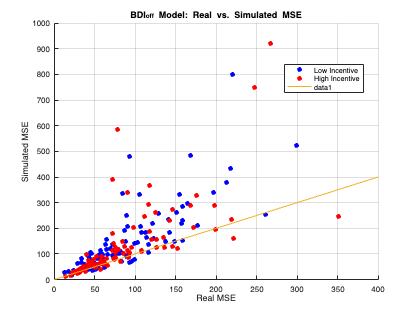


% BDI_off Model
figure;
hold on;
scatter(MSE_real_low, MSE_sim_BDI_off_low, 'b', 'filled', 'o');  % Blue for low incentive
scatter(MSE_real_high, MSE_sim_BDI_off_high, 'r', 'filled', 'o'); % Red for high incentive
hold off;
xlabel('Real MSE');
ylabel('Simulated MSE');
title('BDI_{off} Model: Real vs. Simulated MSE');
legend('Low Incentive', 'High Incentive', 'Location', 'best');
refline(1,0);
grid on;

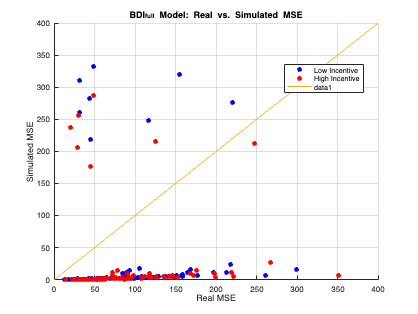


% BDI_full Model
figure;
hold on;
scatter(MSE_real_low, MSE_sim_BDI_full_low, 'b', 'filled', 'o');  % Blue for low incentive
scatter(MSE_real_high, MSE_sim_BDI_full_high, 'r', 'filled', 'o'); % Red for high incentive
hold off;
xlabel('Real MSE');
ylabel('Simulated MSE');
title('BDI_{full} Model: Real vs. Simulated MSE');
legend('Low Incentive', 'High Incentive', 'Location', 'best');
refline(1,0);
grid on;

## HISTOGRAMS of BEST FIT PARAMS

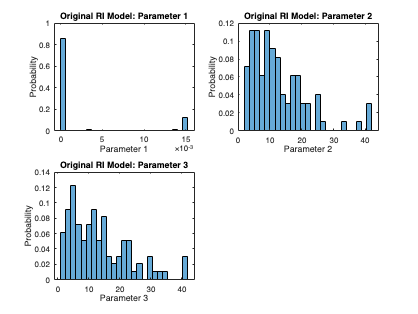

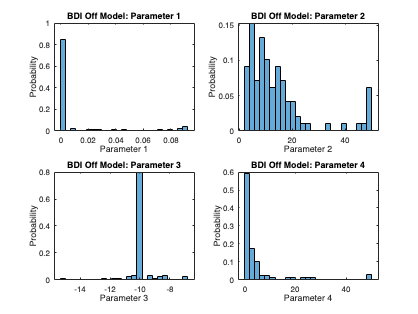

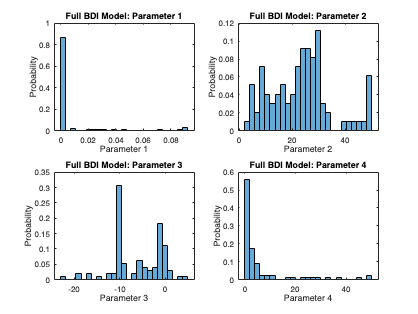

models = {results_RI, results_BDI_off, results_BDI_full};
modelNames = {'Original RI Model', 'BDI Off Model', 'Full BDI Model'};

for m = 1:length(models)
    currResults = models{m};
    numParams = size(currResults.x, 2);
         
    figure('Name', modelNames{m});
    
    for p = 1:numParams
        subplot(ceil(numParams/2), 2, p);  
        histogram(currResults.x(:, p), 'Normalization', 'probability', 'NumBins', 25);
        xlabel(sprintf('Parameter %d', p));
        ylabel('Probability');
        title(sprintf('%s: Parameter %d', modelNames{m}, p));
    end
end


models = {results_RI, results_BDI_off, results_BDI_full};
modelNames = {'Original RI Model', 'BDI Off Model', 'Full BDI Model'};

for m = 1:length(models)
    currResults = models{m};
    numParams = size(currResults.x, 2);
    fprintf('\n%s:\n', modelNames{m});
    for p = 1:numParams
        paramVals = currResults.x(:, p);

        mode_val = mode(paramVals);
        fprintf('  Parameter %d mode: %.4f\n', p, mode_val);
    end
end


Original RI Model:


  Parameter 1 mode: 0.0001
  Parameter 2 mode: 2.6664
  Parameter 3 mode: 1.7417



BDI Off Model:


  Parameter 1 mode: 0.0001
  Parameter 2 mode: 2.2641
  Parameter 3 mode: -15.0207
  Parameter 4 mode: 0.0010



Full BDI Model:


  Parameter 1 mode: 0.0001
  Parameter 2 mode: 2.2639
  Parameter 3 mode: -22.5155
  Parameter 4 mode: 0.0010


## FIGURE 2A Sam's RI Model

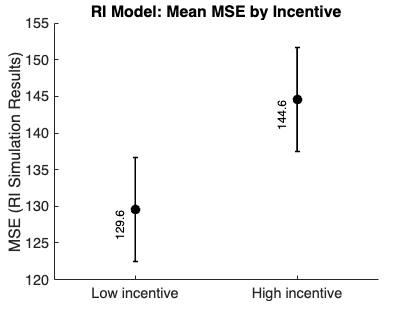

MSE_low_RI    = nan(numSubjects,1);
MSE_high_RI   = nan(numSubjects,1);

for i = 1:numSubjects
    stim      = cleanNJ(i).stimulus;
    synth_est = data_synth_RI(i).estimate;
    cond_low  = cleanNJ(i).incentive == 0.4;
    cond_high = cleanNJ(i).incentive == 2;
    MSE_low_RI(i)  = nanmean((synth_est(cond_low)  - stim(cond_low)).^2);
    MSE_high_RI(i) = nanmean((synth_est(cond_high) - stim(cond_high)).^2);
end

figure; hold on

% means and within-subject SE
means_all_RI = [nanmean(MSE_low_RI), nanmean(MSE_high_RI)];
sems_all_RI = wse([MSE_low_RI, MSE_high_RI]);

h = errorbar([1 2], means_all_RI, sems_all_RI, 'o', 'LineStyle', 'none', 'MarkerSize', 10, 'MarkerFaceColor', 'k', 'Color', 'k', 'LineWidth', 2);

text(0.9, means_all_RI(1), sprintf('%.1f', means_all_RI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'k', 'FontSize', 15, 'Rotation', 90);
text(1.9, means_all_RI(2), sprintf('%.1f', means_all_RI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'k', 'FontSize', 15, 'Rotation', 90);

xlim([0.5 2.5])
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low incentive','High incentive'})
set(gca, 'FontSize', 18)
ylabel('MSE (RI Simulation Results)')
title('RI Model: Mean MSE by Incentive')
hold off

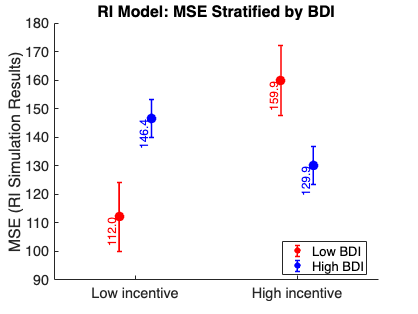


%% stratified by BDI
figure; hold on

% means & SEs for each incentive × BDI cell
means_lowBDI = [nanmean(MSE_low_RI(BDI_low)), nanmean(MSE_high_RI(BDI_low))];
sems_lowBDI = wse([MSE_low_RI(BDI_low), MSE_high_RI(BDI_low)]);
means_highBDI = [nanmean(MSE_low_RI(BDI_high)), nanmean(MSE_high_RI(BDI_high))];
sems_highBDI = wse([MSE_low_RI(BDI_high), MSE_high_RI(BDI_high)]);

% Low-BDI in red 
h1 = errorbar([0.9 1.9], means_lowBDI, sems_lowBDI, 'o', 'LineStyle', 'none', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);

% High-BDI in blue 
h2 = errorbar([1.1 2.1], means_highBDI, sems_highBDI, 'o', 'LineStyle', 'none', 'MarkerSize', 10, 'MarkerFaceColor', 'b', 'Color', 'b', 'LineWidth', 2);

% Low BDI group
text(0.85, means_lowBDI(1), sprintf('%.1f', means_lowBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'r', 'FontSize', 15, 'Rotation', 90);
text(1.85, means_lowBDI(2), sprintf('%.1f', means_lowBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'r', 'FontSize', 15, 'Rotation', 90);

% For High BDI group
text(1.05, means_highBDI(1), sprintf('%.1f', means_highBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'b', 'FontSize', 15, 'Rotation', 90);
text(2.05, means_highBDI(2), sprintf('%.1f', means_highBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'b', 'FontSize', 15, 'Rotation', 90);

xlim([0.5 2.5])
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low incentive','High incentive'})
set(gca, 'FontSize', 18)
ylabel('MSE (RI Simulation Results)')
legend([h1, h2], {'Low BDI','High BDI'}, 'Location', 'Best')
title('RI Model: MSE Stratified by BDI')
hold off

## FIG2A Plots BDI Off

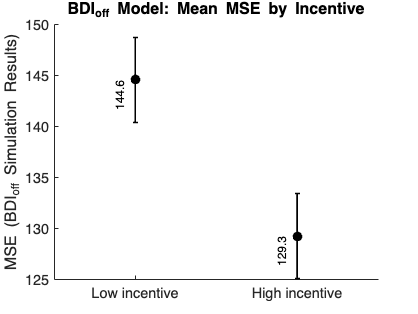

numSubjects = numel(cleanNJ);

% Preallocate arrays
MSE_low_BDI_off = nan(numSubjects, 1);
MSE_high_BDI_off = nan(numSubjects, 1);

% Calculate MSE for each subject
for i = 1:numSubjects
    stim = cleanNJ(i).stimulus;
    synth_est = data_synth_BDI_off(i).estimate;
    cond_low = cleanNJ(i).incentive == 0.4;
    cond_high = cleanNJ(i).incentive == 2;
    MSE_low_BDI_off(i) = nanmean((synth_est(cond_low) - stim(cond_low)).^2);
    MSE_high_BDI_off(i) = nanmean((synth_est(cond_high) - stim(cond_high)).^2);
end

% All subjects plot
figure; hold on
% means and within-subject SE
means_all_BDI_off = [nanmean(MSE_low_BDI_off), nanmean(MSE_high_BDI_off)];
sems_all_BDI_off = wse([MSE_low_BDI_off, MSE_high_BDI_off]);

% Plot
h = errorbar([1 2], means_all_BDI_off, sems_all_BDI_off, 'o', 'LineStyle', 'none', 'MarkerSize', 10, 'MarkerFaceColor', 'k', 'Color', 'k', 'LineWidth', 2);

xlim([0.5 2.5])

text(0.9, means_all_BDI_off(1), sprintf('%.1f', means_all_BDI_off(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'k', 'Rotation', 90, 'FontSize', 15);

text(1.9, means_all_BDI_off(2), sprintf('%.1f', means_all_BDI_off(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'k', 'Rotation', 90, 'FontSize', 15);

set(gca, 'XTick', [1 2], 'XTickLabel', {'Low incentive','High incentive'})
set(gca, 'FontSize', 18)
ylabel('MSE (BDI_{off} Simulation Results)')
title('BDI_{off} Model: Mean MSE by Incentive')
hold off

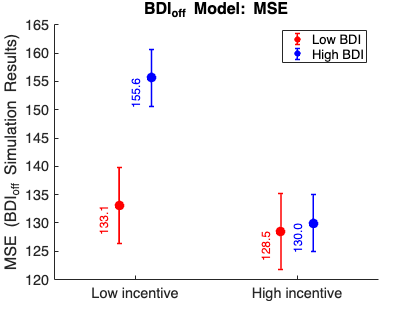


figure; hold on
% compute means & SEs for each incentive x BDI cell
means_lowBDI = [nanmean(MSE_low_BDI_off(BDI_low)), nanmean(MSE_high_BDI_off(BDI_low))];
sems_lowBDI = wse([MSE_low_BDI_off(BDI_low), MSE_high_BDI_off(BDI_low)]);
means_highBDI = [nanmean(MSE_low_BDI_off(BDI_high)), nanmean(MSE_high_BDI_off(BDI_high))];
sems_highBDI = wse([MSE_low_BDI_off(BDI_high), MSE_high_BDI_off(BDI_high)]);

% Low-BDI 
h1 = errorbar([0.9 1.9], means_lowBDI, sems_lowBDI, 'o', 'LineStyle', 'none', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);

% High-BDI 
h2 = errorbar([1.1 2.1], means_highBDI, sems_highBDI, 'o', 'LineStyle', 'none', 'MarkerSize', 10, 'MarkerFaceColor', 'b', 'Color', 'b', 'LineWidth', 2);

% Add text 
% For Low BDI group
text(0.8, means_lowBDI(1), sprintf('%.1f', means_lowBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'r', 'Rotation', 90, 'FontSize', 15);
text(1.8, means_lowBDI(2), sprintf('%.1f', means_lowBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'r', 'Rotation', 90, 'FontSize', 15);

% For High BDI group
text(1.0, means_highBDI(1), sprintf('%.1f', means_highBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'b', 'Rotation', 90, 'FontSize', 15);
text(2.0, means_highBDI(2), sprintf('%.1f', means_highBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', 'b', 'Rotation', 90, 'FontSize', 15);xlim([0.5 2.5])

set(gca, 'XTick', [1 2], 'XTickLabel', {'Low incentive','High incentive'})
set(gca, 'FontSize', 18)
ylabel('MSE (BDI_{off} Simulation Results)')
legend([h1, h2], {'Low BDI','High BDI'}, 'Location', 'Best')
title('BDI_{off} Model: MSE')
hold off

## FIGURE 3B Plot (Fitted Alphas per Incentive Condition)

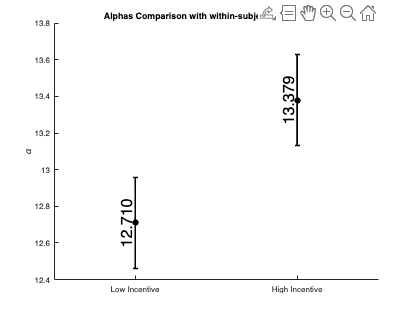

% Fitted alpha parameters for each incentive condition
alpha_low  = results_RI.x(:,2); 
alpha_high = results_RI.x(:,3);

% Combine the low and high alpha values into a single matrix:
X = [alpha_low, alpha_high];

% Compute within-subject error bars and raw means using the wse function.
[se, m] = wse(X, 2);

% Plot the results
figure; hold on;
% Plot the low-incentive condition using the raw mean and within-subject SE.
errorbar(1, m(1), se(1), 'ko', 'LineWidth',2, 'MarkerFaceColor','k');
% Plot the high-incentive condition.
errorbar(2, m(2), se(2), 'ko', 'LineWidth',2, 'MarkerFaceColor','k');

xlim([0.5,2.5]);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low Incentive','High Incentive'});
ylabel('\alpha');
title('Alphas Comparison with within-subject SEM (Sam RI)');

% Add text annotations for the raw means
text(1, m(1), sprintf('%.3f', m(1)), 'Rotation', 90, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 20);
text(2, m(2), sprintf('%.3f', m(2)), 'Rotation', 90, 'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'bottom', 'FontSize', 20);

hold off;

xlim([0.50 2.50])

[~, p, ~, stats] = ttest(alpha_low, alpha_high);

t_value  = stats.tstat;
df       = stats.df;
p_value  = p;

fprintf('t(%d) = %.2f, p = %.4f\n', df, t_value, p_value);

t(97) = -1.35, p = 0.1818


%% STRATIFY SUBJECTS AND COMPUTE FITTED ALPHAS 
numSubjects = size(results_RI.x,1);

subject_BDI = scaledBDI  

subject_BDI =     0.3542
    0.0625
         0
    0.1458
    0.0417
         0
    0.6875
         0
    0.6042
    0.2083


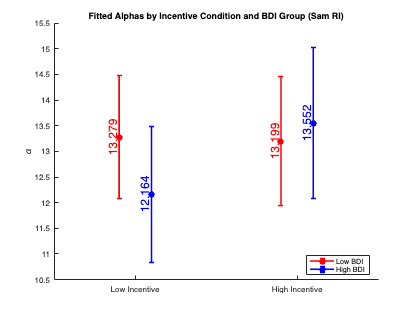


median_BDI_value = median(subject_BDI);

lowBdiIndices = find(subject_BDI < median_BDI_value);
highBdiIndices = find(subject_BDI >= median_BDI_value);

alpha_low = results_RI.x(:,2);   
alpha_high = results_RI.x(:,3);  

% low BDI:
alpha_low_lowBDI = mean(alpha_low(lowBdiIndices));
alpha_high_lowBDI = mean(alpha_high(lowBdiIndices));
se_low_lowBDI = std(alpha_low(lowBdiIndices)) / sqrt(length(lowBdiIndices));
se_high_lowBDI = std(alpha_high(lowBdiIndices)) / sqrt(length(lowBdiIndices));

% high BDI:
alpha_low_highBDI = mean(alpha_low(highBdiIndices));
alpha_high_highBDI = mean(alpha_high(highBdiIndices));
se_low_highBDI = std(alpha_low(highBdiIndices)) / sqrt(length(highBdiIndices));
se_high_highBDI = std(alpha_high(highBdiIndices)) / sqrt(length(highBdiIndices));

%%Fitted Alphas by Incentive Condition and BDI Group
x_low_lowBDI = 0.9;    % Low incentive, Low BDI
x_low_highBDI = 1.1;   % Low incentive, High BDI
x_high_lowBDI = 1.9;   % High incentive, Low BDI
x_high_highBDI = 2.1;  % High incentive, High BDI

figure; hold on;
% Plot errorbars for low incentive:
errorbar(x_low_lowBDI, alpha_low_lowBDI, se_low_lowBDI, 'ro-', 'LineWidth',2, 'MarkerFaceColor','r');
errorbar(x_low_highBDI, alpha_low_highBDI, se_low_highBDI, 'bo-', 'LineWidth',2, 'MarkerFaceColor','b');

% Plot errorbars for high incentive:
errorbar(x_high_lowBDI, alpha_high_lowBDI, se_high_lowBDI, 'ro-', 'LineWidth',2, 'MarkerFaceColor','r');
errorbar(x_high_highBDI, alpha_high_highBDI, se_high_highBDI, 'bo-', 'LineWidth',2, 'MarkerFaceColor','b');

xlim([0.5 2.5]);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low Incentive','High Incentive'});
ylabel('\alpha');
title('Fitted Alphas by Incentive Condition and BDI Group (Sam RI)');
legend({'Low BDI','High BDI'}, 'Location','Best');

text(x_low_lowBDI, alpha_low_lowBDI, sprintf('%.3f', alpha_low_lowBDI), 'Rotation',90, ...
    'FontSize', 15,'HorizontalAlignment','center','VerticalAlignment','bottom','Color','r');
text(x_low_highBDI, alpha_low_highBDI, sprintf('%.3f', alpha_low_highBDI), 'Rotation',90, ...
    'FontSize', 15,'HorizontalAlignment','center','VerticalAlignment','bottom','Color','b');
text(x_high_lowBDI, alpha_high_lowBDI, sprintf('%.3f', alpha_high_lowBDI), 'Rotation',90, ...
    'FontSize', 15,'HorizontalAlignment','center','VerticalAlignment','bottom','Color','r');
text(x_high_highBDI, alpha_high_highBDI, sprintf('%.3f', alpha_high_highBDI), 'Rotation',90, ...
    'FontSize', 15,'HorizontalAlignment','center','VerticalAlignment','bottom','Color','b');
hold off;

## FIGURE 3B Plot (BDI_OFF)

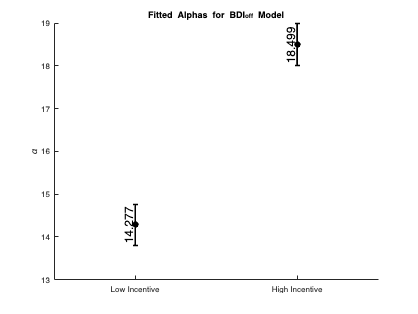

% Fitted alpha parameters for BDI_off model (BDI_intact = 0)

% alpha_low = Beta0, and alpha_high = Beta0 + Beta2
alpha_low_BDI_off  = results_BDI_off.x(:,2);
alpha_high_BDI_off = alpha_low_BDI_off + results_BDI_off.x(:,4);

% Combine the low and high alpha values into a single matrix:
X_BDI_off = [alpha_low_BDI_off, alpha_high_BDI_off];

% Compute within-subject error bars and raw means using the wse function.
[se_BDI_off, m_BDI_off] = wse(X_BDI_off, 2);

% Plot the results for the BDI_off model
figure; hold on;
errorbar(1, nanmean(m_BDI_off(1)), se_BDI_off(1), 'ko', 'LineWidth',2, 'MarkerFaceColor','k');
errorbar(2, nanmean(m_BDI_off(2)), se_BDI_off(2), 'ko', 'LineWidth',2, 'MarkerFaceColor','k');
xlim([0.5,2.5]);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low Incentive','High Incentive'});
ylabel('\alpha');
title('Fitted Alphas for BDI_{off} Model');
text(1, m_BDI_off(1), sprintf('%.3f', m_BDI_off(1)), 'Rotation', 90, ...
   'FontSize', 15, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
text(2, m_BDI_off(2), sprintf('%.3f', m_BDI_off(2)), 'Rotation', 90, ...
    'FontSize', 15,'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
hold off;

[~, p_BDI_off, ~, stats_BDI_off] = ttest(alpha_low_BDI_off, alpha_high_BDI_off);
fprintf('BDI_off Model: t(%d) = %.2f, p = %.4f\n', stats_BDI_off.df, stats_BDI_off.tstat, p_BDI_off);

BDI_off Model: t(97) = -4.33, p = 0.0000


alpha_low_BDI_off  = results_BDI_off.x(:,2);
alpha_high_BDI_off = alpha_low_BDI_off + results_BDI_off.x(:,4);

%% Stratify subjects by normalized BDI
numSubjects = size(results_BDI_off.x,1);

subject_BDI_off = scaledBDI

subject_BDI_off =     0.3542
    0.0625
         0
    0.1458
    0.0417
         0
    0.6875
         0
    0.6042
    0.2083


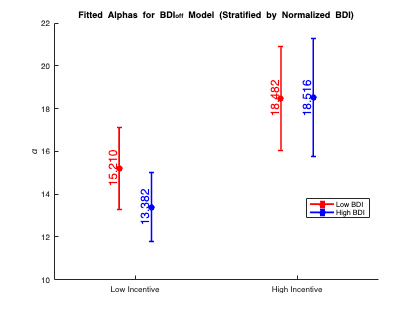

median_BDI_val = median(subject_BDI_off);

lowBdiIndices = find(subject_BDI_off < median_BDI_val);
highBdiIndices = find(subject_BDI_off >= median_BDI_val);

% For low incentive:
alpha_low_lowBDI = mean(alpha_low_BDI_off(lowBdiIndices));
alpha_low_highBDI = mean(alpha_low_BDI_off(highBdiIndices));
se_low_lowBDI = std(alpha_low_BDI_off(lowBdiIndices)) / sqrt(length(lowBdiIndices));
se_low_highBDI = std(alpha_low_BDI_off(highBdiIndices)) / sqrt(length(highBdiIndices));

% For high incentive:
alpha_high_lowBDI = mean(alpha_high_BDI_off(lowBdiIndices));
alpha_high_highBDI = mean(alpha_high_BDI_off(highBdiIndices));
se_high_lowBDI = std(alpha_high_BDI_off(lowBdiIndices)) / sqrt(length(lowBdiIndices));
se_high_highBDI = std(alpha_high_BDI_off(highBdiIndices)) / sqrt(length(highBdiIndices));

x_low_low = 0.9;    % Low incentive, Low BDI group
x_low_high = 1.1;   % Low incentive, High BDI group
x_high_low = 1.9;   % High incentive, Low BDI group
x_high_high = 2.1;  % High incentive, High BDI group

figure; hold on;
% Plot low incentive:
errorbar(x_low_low, alpha_low_lowBDI, se_low_lowBDI, 'ro-', 'LineWidth',2, 'MarkerFaceColor','r');
errorbar(x_low_high, alpha_low_highBDI, se_low_highBDI, 'bo-', 'LineWidth',2, 'MarkerFaceColor','b');
% Plot high incentive:
errorbar(x_high_low, alpha_high_lowBDI, se_high_lowBDI, 'ro-', 'LineWidth',2, 'MarkerFaceColor','r');
errorbar(x_high_high, alpha_high_highBDI, se_high_highBDI, 'bo-', 'LineWidth',2, 'MarkerFaceColor','b');

xlim([0.5 2.5]);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low Incentive','High Incentive'});
ylabel('\alpha');
title('Fitted Alphas for BDI_{off} Model (Stratified by Normalized BDI)');
legend({'Low BDI','High BDI'}, 'Location','Best');

% Annotate each point with the numeric value
text(x_low_low, alpha_low_lowBDI, sprintf('%.3f', alpha_low_lowBDI), 'Rotation',90, ...
    'HorizontalAlignment','center','VerticalAlignment','bottom','Color','r', 'FontSize', 15);
text(x_low_high, alpha_low_highBDI, sprintf('%.3f', alpha_low_highBDI), 'Rotation',90, ...
    'HorizontalAlignment','center','VerticalAlignment','bottom','Color','b', 'FontSize', 15);
text(x_high_low, alpha_high_lowBDI, sprintf('%.3f', alpha_high_lowBDI), 'Rotation',90, ...
    'HorizontalAlignment','center','VerticalAlignment','bottom','Color','r', 'FontSize', 15);
text(x_high_high, alpha_high_highBDI, sprintf('%.3f', alpha_high_highBDI), 'Rotation',90, ...
    'HorizontalAlignment','center','VerticalAlignment','bottom','Color','b', 'FontSize', 15);
hold off;

## FIGURE 3B Plot (BDI_FULL)

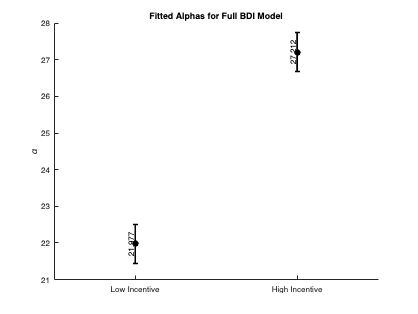

% First, compute each subject's overall BDI.
numSubjects = size(results_BDI_full.x, 1);
subject_BDI = BDI(1:numSubjects);

% Fitted alpha parameters for the Full BDI model (BDI_intact = 1)
% For low incentive trials: alpha_low = Beta0 + Beta1*(BDI)
alpha_low_BDI_full  = results_BDI_full.x(:,2) + results_BDI_full.x(:,3) .* subject_BDI;
% For high incentive trials: alpha_high = alpha_low + Beta2
alpha_high_BDI_full = alpha_low_BDI_full + results_BDI_full.x(:,4);

% Combine into a single matrix:
X_BDI_full = [alpha_low_BDI_full, alpha_high_BDI_full];

% Compute within-subject error bars and means using wse.
[se_BDI_full, m_BDI_full] = wse(X_BDI_full, 2);

% Plot the results for the Full BDI model
figure; hold on;
errorbar(1, nanmean(m_BDI_full(1)), se_BDI_full(1), 'ko', 'LineWidth',2, 'MarkerFaceColor','k');
errorbar(2, nanmean(m_BDI_full(2)), se_BDI_full(2), 'ko', 'LineWidth',2, 'MarkerFaceColor','k');
xlim([0.5,2.5]);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low Incentive','High Incentive'});
ylabel('\alpha');
title('Fitted Alphas for Full BDI Model');
text(1, m_BDI_full(1), sprintf('%.3f', m_BDI_full(1)), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
text(2, m_BDI_full(2), sprintf('%.3f', m_BDI_full(2)), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
hold off;

[~, p_BDI_full, ~, stats_BDI_full] = ttest(alpha_low_BDI_full, alpha_high_BDI_full);
fprintf('Full BDI Model: t(%d) = %.2f, p = %.4f\n', stats_BDI_full.df, stats_BDI_full.tstat, p_BDI_full);

Full BDI Model: t(97) = -4.88, p = 0.0000


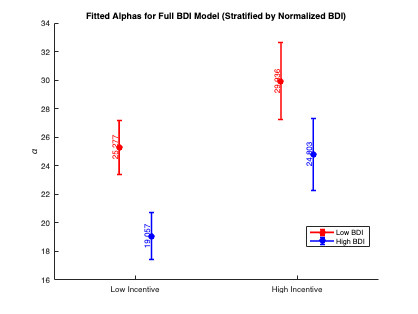

numSubjects = size(results_BDI_full.x, 1);

subject_BDI = BDI(1:numSubjects);

alpha_low_BDI_full = results_BDI_full.x(:,2) + results_BDI_full.x(:,3) .* subject_BDI;
% For high incentive trials: α_high = α_low + β₂
alpha_high_BDI_full = alpha_low_BDI_full + results_BDI_full.x(:,4);

% Now stratify subjects by their normalized BDI using the median
median_BDI_val = median(subject_BDI);
lowBdiIndices = find(subject_BDI < median_BDI_val);
highBdiIndices = find(subject_BDI >= median_BDI_val);

% Low incentive:
alpha_low_lowBDI = mean(alpha_low_BDI_full(lowBdiIndices));
se_low_lowBDI    = std(alpha_low_BDI_full(lowBdiIndices)) / sqrt(length(lowBdiIndices));

alpha_low_highBDI = mean(alpha_low_BDI_full(highBdiIndices));
se_low_highBDI    = std(alpha_low_BDI_full(highBdiIndices)) / sqrt(length(highBdiIndices));

% High incentive:
alpha_high_lowBDI = mean(alpha_high_BDI_full(lowBdiIndices));
se_high_lowBDI    = std(alpha_high_BDI_full(lowBdiIndices)) / sqrt(length(lowBdiIndices));

alpha_high_highBDI = mean(alpha_high_BDI_full(highBdiIndices));
se_high_highBDI    = std(alpha_high_BDI_full(highBdiIndices)) / sqrt(length(highBdiIndices));

x_low_low  = 0.9;  % Low incentive, Low BDI
x_low_high = 1.1;  % Low incentive, High BDI
x_high_low = 1.9;  % High incentive, Low BDI
x_high_high= 2.1;  % High incentive, High BDI

figure; hold on;
% Plot low incentive condition:
errorbar(x_low_low, alpha_low_lowBDI, se_low_lowBDI, 'ro-', 'LineWidth',2, 'MarkerFaceColor','r');
errorbar(x_low_high, alpha_low_highBDI, se_low_highBDI, 'bo-', 'LineWidth',2, 'MarkerFaceColor','b');

% Plot high incentive condition:
errorbar(x_high_low, alpha_high_lowBDI, se_high_lowBDI, 'ro-', 'LineWidth',2, 'MarkerFaceColor','r');
errorbar(x_high_high, alpha_high_highBDI, se_high_highBDI, 'bo-', 'LineWidth',2, 'MarkerFaceColor','b');

xlim([0.5 2.5]);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low Incentive','High Incentive'});
ylabel('\alpha');
title('Fitted Alphas for Full BDI Model (Stratified by Normalized BDI)');
legend({'Low BDI','High BDI'}, 'Location','Best');

% Annotate each point with its mean value:
text(x_low_low, alpha_low_lowBDI, sprintf('%.3f', alpha_low_lowBDI), 'Rotation',90, 'HorizontalAlignment','center','VerticalAlignment','bottom','Color','r');
text(x_low_high, alpha_low_highBDI, sprintf('%.3f', alpha_low_highBDI), 'Rotation',90, 'HorizontalAlignment','center','VerticalAlignment','bottom','Color','b');
text(x_high_low, alpha_high_lowBDI, sprintf('%.3f', alpha_high_lowBDI), 'Rotation',90, 'HorizontalAlignment','center','VerticalAlignment','bottom','Color','r');
text(x_high_high, alpha_high_highBDI, sprintf('%.3f', alpha_high_highBDI), 'Rotation',90, 'HorizontalAlignment','center','VerticalAlignment','bottom','Color','b');
hold off;

## Alphas as a Function of BDI Scores

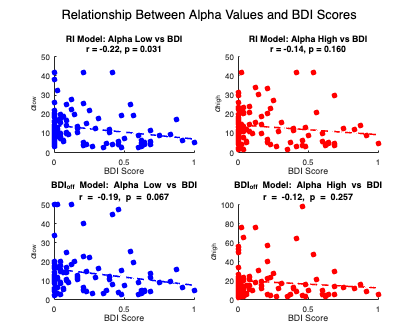

% Create scatter plots of alpha values vs BDI scores for both models
figure;

% RI MODEL 
subplot(2,2,1);
scatter(scaledBDI, results_RI.x(:,2), 50, 'b', 'filled');
hold on;

% Add best fit line
p = polyfit(scaledBDI, results_RI.x(:,2), 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'b--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, results_RI.x(:,2), 'rows', 'complete');
title(sprintf('RI Model: Alpha Low vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{low}');

subplot(2,2,2);
scatter(scaledBDI, results_RI.x(:,3), 50, 'r', 'filled');
hold on;

% Add best fit line
p = polyfit(scaledBDI, results_RI.x(:,3), 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'r--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, results_RI.x(:,3), 'rows', 'complete');
title(sprintf('RI Model: Alpha High vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{high}');

% BDI_OFF MODEL 

alpha_low_BDI_off = results_BDI_off.x(:,2);
alpha_high_BDI_off = alpha_low_BDI_off + results_BDI_off.x(:,4);

subplot(2,2,3);
scatter(scaledBDI, alpha_low_BDI_off, 50, 'b', 'filled');
hold on;

% Add best fit line
p = polyfit(scaledBDI, alpha_low_BDI_off, 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'b--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, alpha_low_BDI_off, 'rows', 'complete');
title(sprintf('BDI_{off} Model: Alpha Low vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{low}');

subplot(2,2,4);
scatter(scaledBDI, alpha_high_BDI_off, 50, 'r', 'filled');
hold on;

% Add best fit line
p = polyfit(scaledBDI, alpha_high_BDI_off, 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'r--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, alpha_high_BDI_off, 'rows', 'complete');
title(sprintf('BDI_{off} Model: Alpha High vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{high}');

% Adjust figure size and layout
set(gcf, 'Position', [100, 100, 1000, 800]);
sgtitle('Relationship Between Alpha Values and BDI Scores', 'FontSize', 16);

hold off;

% RI Subjects Sorted by MSE Difference

numSubjects = numel(cleanNJ);
MSE_diff_RI = zeros(numSubjects, 1);
MSE_diff_low_inc = zeros(numSubjects, 1);
MSE_diff_high_inc = zeros(numSubjects, 1);
subject_ids = zeros(numSubjects, 1);
bdi_values = zeros(numSubjects, 1);

% parameters
tau_values = zeros(numSubjects, 1);
alpha_low_values = zeros(numSubjects, 1);
alpha_high_values = zeros(numSubjects, 1);

lambda0 = 12/(30^2);
lambda_low_values = zeros(numSubjects, 1);
lambda_high_values = zeros(numSubjects, 1);
w_low_values = zeros(numSubjects, 1);
w_high_values = zeros(numSubjects, 1);

for i = 1:numSubjects
    real_est = cleanNJ(i).estimate;
    synth_est = data_synth_RI(i).estimate;
    
    cond_low = cleanNJ(i).incentive == 0.4;
    cond_high = cleanNJ(i).incentive == 2;
    
    MSE_diff_RI(i) = nanmean((synth_est - real_est).^2);
    
    MSE_diff_low_inc(i) = nanmean((synth_est(cond_low) - real_est(cond_low)).^2);
    MSE_diff_high_inc(i) = nanmean((synth_est(cond_high) - real_est(cond_high)).^2);
    
    subject_ids(i) = cleanNJ(i).subject;
    bdi_values(i) = BDI_low(i); % 1 = low BDI, 0 = high BDI
    
    tau_values(i) = results_RI.x(i, 1);
    alpha_low_values(i) = results_RI.x(i, 2);
    alpha_high_values(i) = results_RI.x(i, 3);
    
    lambda_low_values(i) = max(2*alpha_low_values(i) - lambda0, 0.0001);
    lambda_high_values(i) = max(2*alpha_high_values(i) - lambda0, 0.0001);
    
    w_low_values(i) = lambda_low_values(i)/(lambda_low_values(i) + lambda0);
    w_high_values(i) = lambda_high_values(i)/(lambda_high_values(i) + lambda0);
end

% Create a table with all the data
mse_table = table(subject_ids, MSE_diff_RI, MSE_diff_low_inc, MSE_diff_high_inc, ...
                  bdi_values, tau_values, alpha_low_values, alpha_high_values, ...
                  lambda_low_values, lambda_high_values, w_low_values, w_high_values, ...
                  'VariableNames', {'SubjectID', 'MSE_Overall', 'MSE_LowInc', 'MSE_HighInc', ...
                  'LowBDI', 'Tau', 'Alpha_Low', 'Alpha_High', ...
                  'Lambda_Low', 'Lambda_High', 'W_Low', 'W_High'});
